# Cropping the cell area

## Method 1 Pyramid

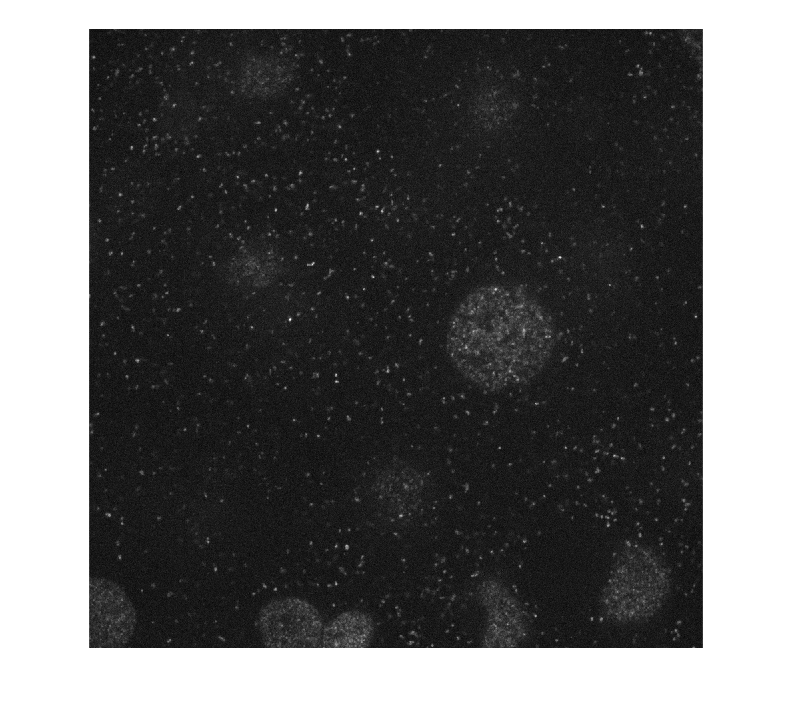

I = imread("fiji.app/oblong_gel_ddw_sub.tif",106);
imshow(I,[])

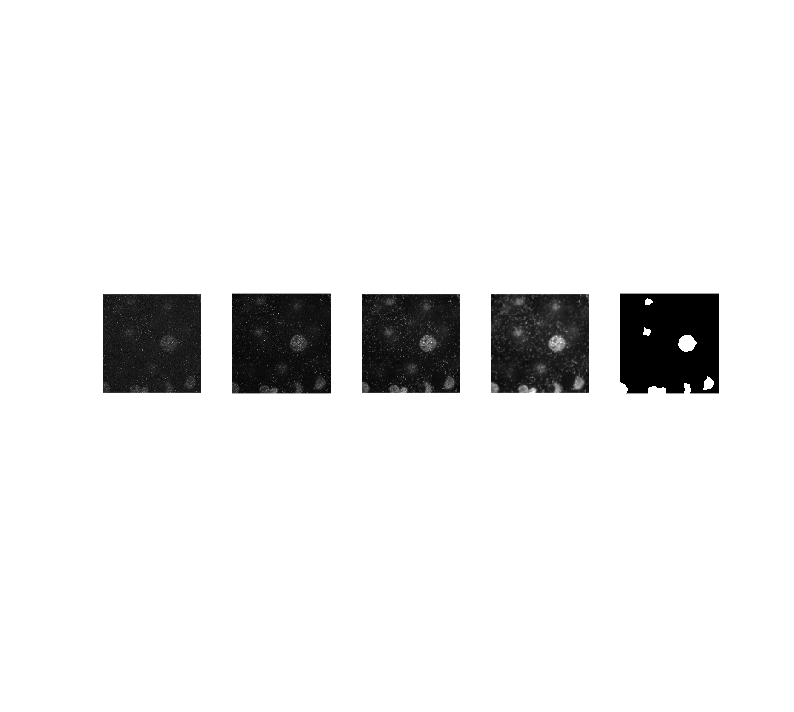

I1 = impyramid(I, 'reduce');
I2 = impyramid(I1, 'reduce');
I3 = impyramid(I2, 'reduce');
I4 = impyramid(I3, 'reduce');
subplot(151)
imshow(I,[])
subplot(152)
imshow(I1,[])
subplot(153)
imshow(I2,[])
subplot(154)
imshow(I3,[])
subplot(155)
I4Thers =  I3 > 135;
I4Thers = bwareaopen(I4Thers,50);
I4Thers = imclose(I4Thers, strel('disk',5));
I4Thers = uint16(imresize(I4Thers,8));
imshow(I4Thers,[])

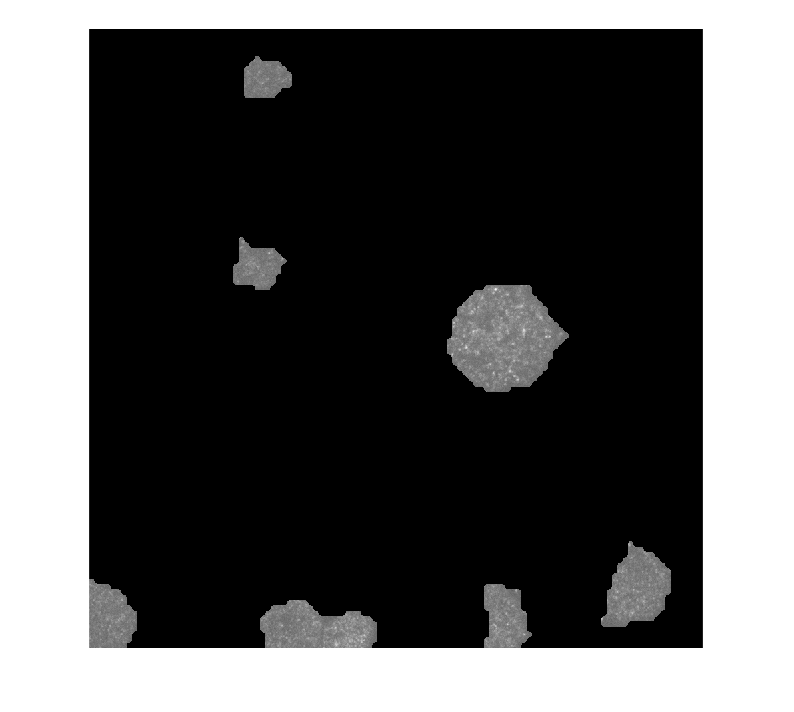

Icrop = I.*I4Thers;
figure
imshow(Icrop,[])

## Method 2 Morphlogic opreation

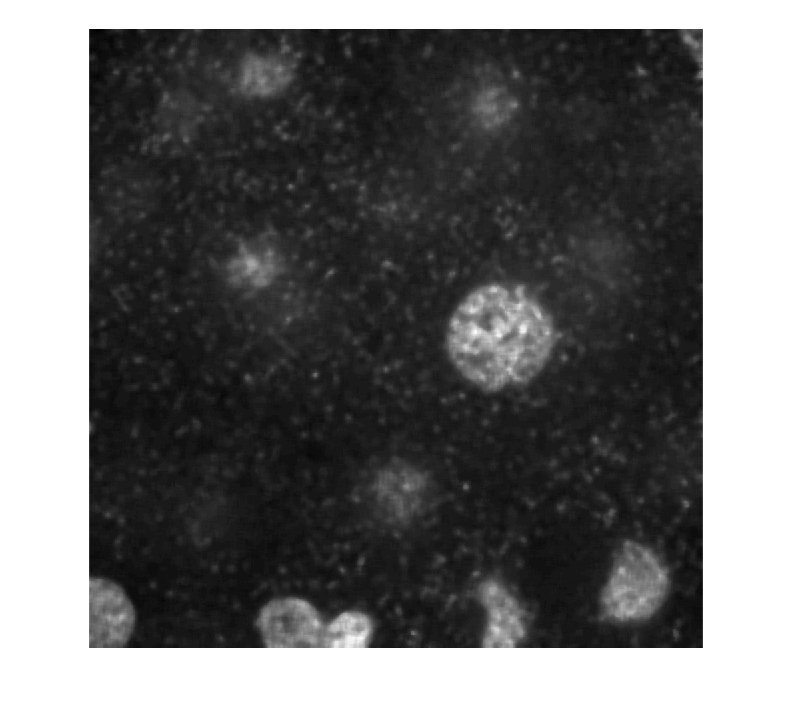

I = imread("fiji.app/oblong_gel_ddw_sub.tif",106);
Imed = medfilt2(I,[12 12],'symmetric');
imshow(Imed,[])

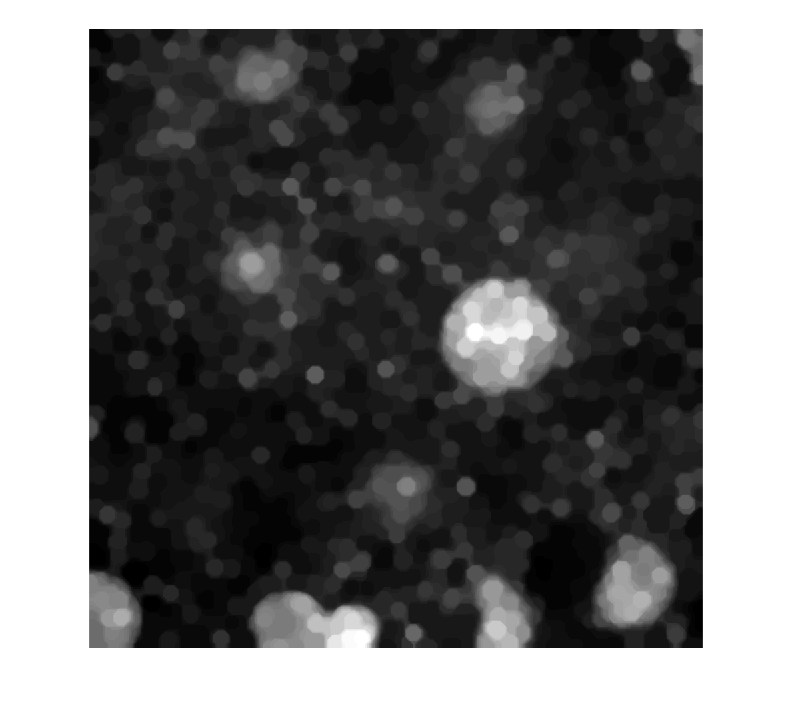

Id = imdilate(Imed,strel('disk',20));
Ie = imerode(Id,strel('disk',10));
imshow(Ie,[])

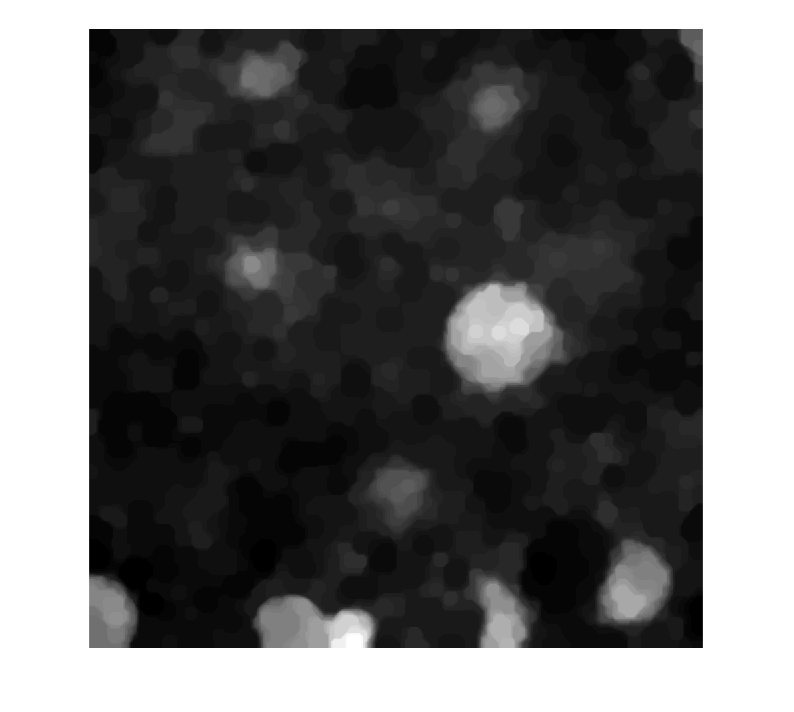

Id = imdilate(Ie,strel('disk',5));
Ie = imerode(Id,strel('disk',20));
Id = imdilate(Ie,strel('disk',10));
imshow(Id,[])

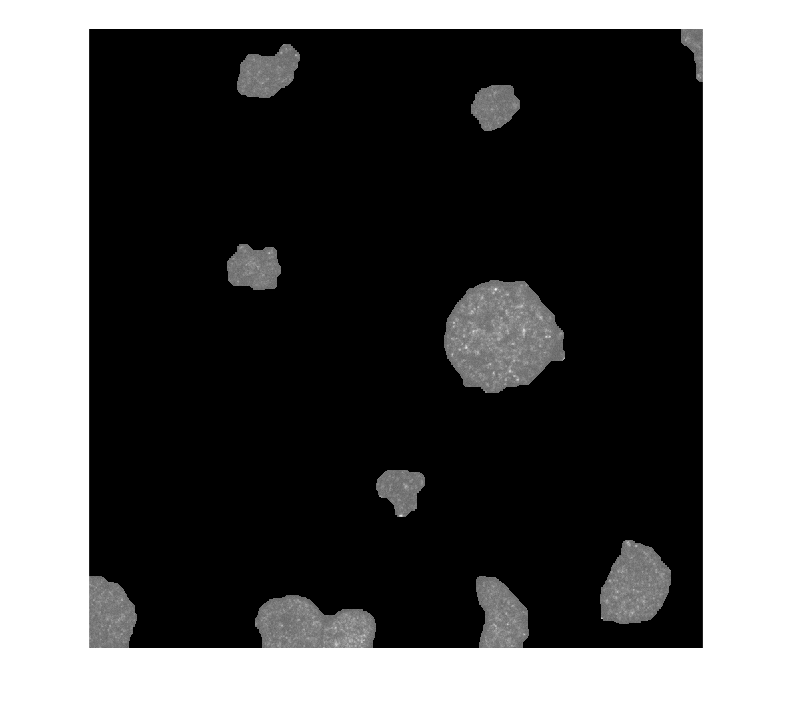

Imask = Id > 135;
Icrop = I.*uint16(Imask);
imshow(Icrop,[])

## Method 3 Object paramter filtering

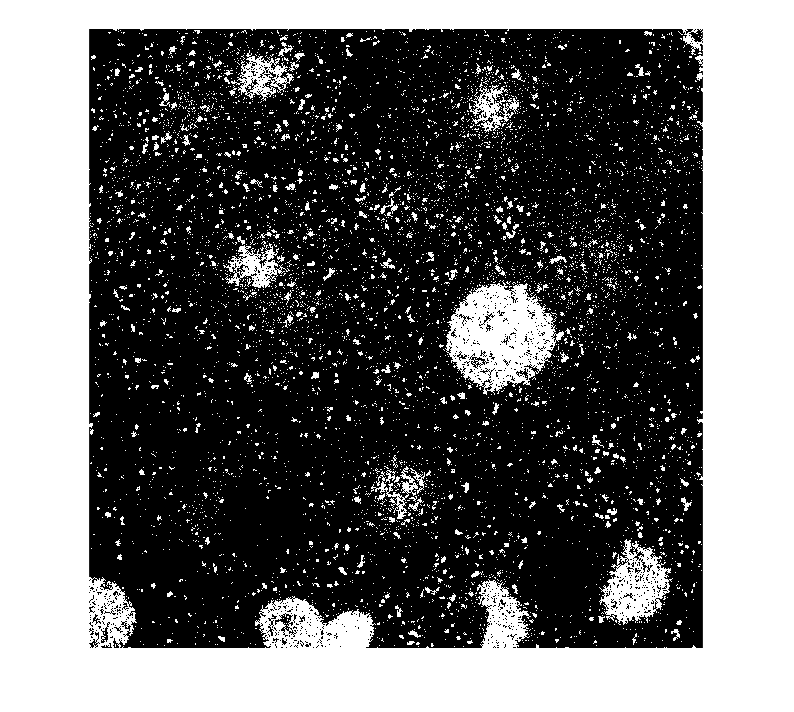


I = imread("fiji.app/oblong_gel_ddw_sub.tif",106);
Ibw = I > 135;
imshow(Ibw,[])

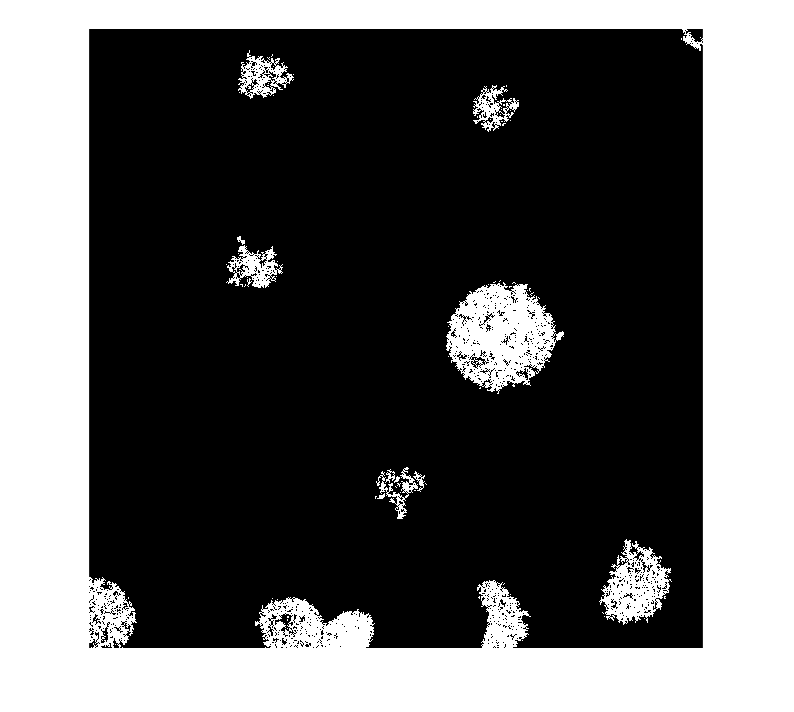

Props = regionprops(Ibw,'all');
[~,idx]=sort([Props.Area]);
Props = Props(idx);
Ifilt = bwpropfilt(Ibw,'EulerNumber',[-2000,-10]);
imshow(Ifilt)

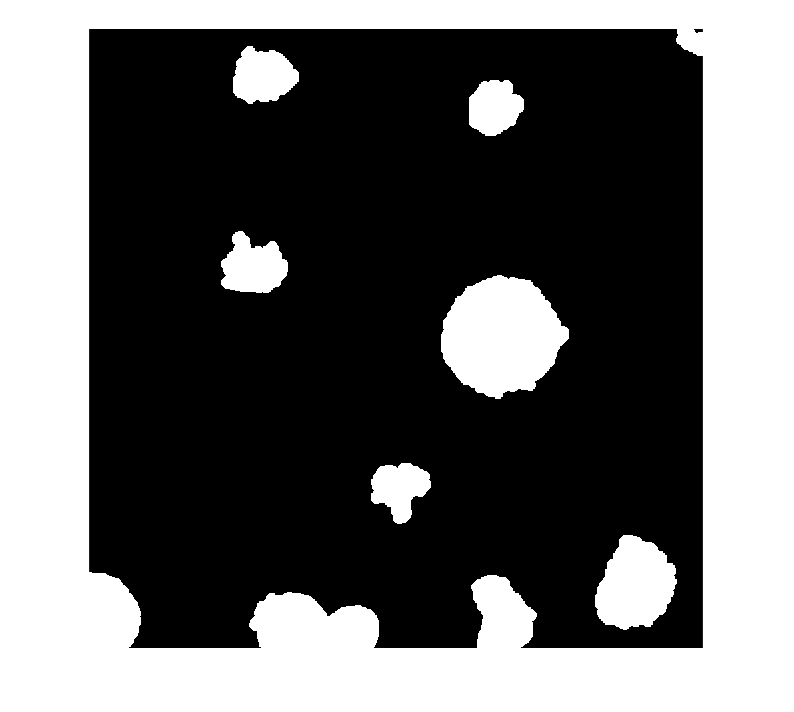

Idial = imdilate(Ifilt,strel('disk',8,4));
Ifill = imfill(Idial,'holes');
imshow(Ifill)

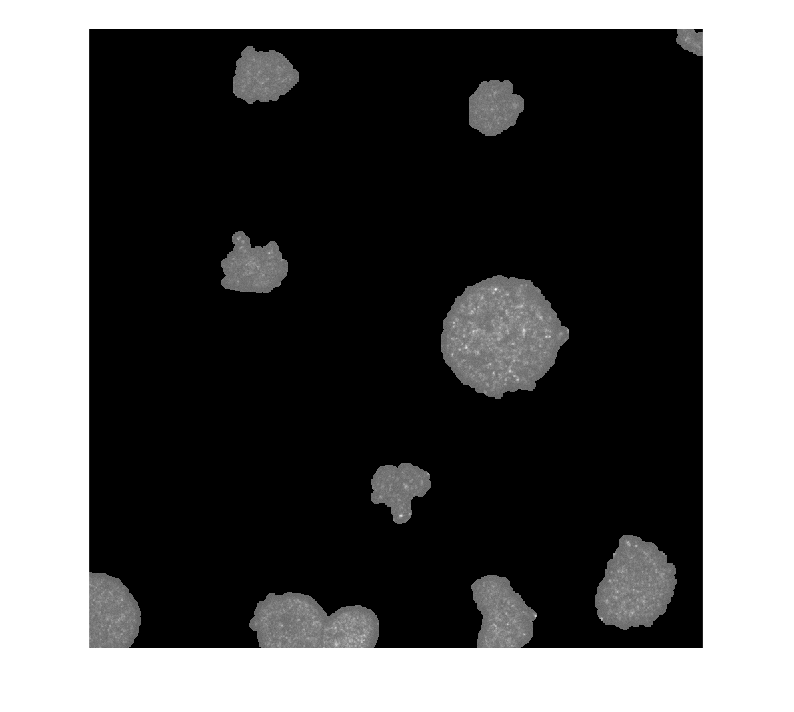

Icrop = I.*uint16(Ifill);
imshow(Icrop,[])

I = imread("fiji.app/oblong_gel_ddw_sub.tif",106);
imshow(I,[]);